# CP圆弧轨迹规划 - 笛卡尔空间连续轨迹

clear; clc; close all;

## 创建机器人模型

% 定义连杆长度
d4_val = 0.187 + 0.063; 

% 建立 Standard DH 模型
L(1) = Link('revolute', 'd', 0.12202, 'a', 0.1, 'alpha', -pi/2, 'standard');
L(2) = Link('revolute', 'd', 0, 'a', 0.25, 'alpha', 0, 'standard', 'offset', -pi/2);
L(3) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard', 'offset', pi);
L(4) = Link('revolute', 'd', d4_val, 'a', 0, 'alpha', -pi/2, 'standard');
L(5) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard');
L(6) = Link('revolute', 'd', 0.0595, 'a', 0, 'alpha', 0, 'standard');
EpsonC3_M = SerialLink(L, 'name', 'Epson C3 A601', 'base', transl(0,0,0.198));
file_path = '.\EpsonC3A601_SW\';

## 设置工作空间

workspace = [-0.5 0.5 -0.5 0.5 0 0.8];
EpsonC3_M.plotopt = {'workspace', workspace, 'scale', 0.5};

% 定义关节角度限制
qlim = [
    -170/180*pi, 170/180*pi;    % 关节1限制
    -160/180*pi, 65/180*pi;     % 关节2限制
    -51/180*pi, 225/180*pi;     % 关节3限制
    -200/180*pi, 200/180*pi;    % 关节4限制
    -135/180*pi, 135/180*pi;    % 关节5限制
    -2*pi, 2*pi;                % 关节6限制
];

## 主程序：执行圆弧轨迹规划

% 定义圆弧的三个点（起点、中间点、终点）
start_point = [0.3, -0.2, 0.5];    % 起点
via_point = [0.35, 0.2, 0.6];   % 中间点
end_point = [0.1, 0.4, 0.2];      % 终点

% 圆弧参数
num_points = 50;  % 圆弧采样点数

% 生成圆弧路径，arc_points为圆弧上的采样点
[arc_points, arc_length, center, radius] = generate_arc(start_point, via_point, end_point, num_points);

圆弧规划完成:
  圆心: [0.188, 0.077, 0.311]
  半径: 0.353 m
  弧长: 1.018 m
  角度范围: 37.6° 到 202.7°


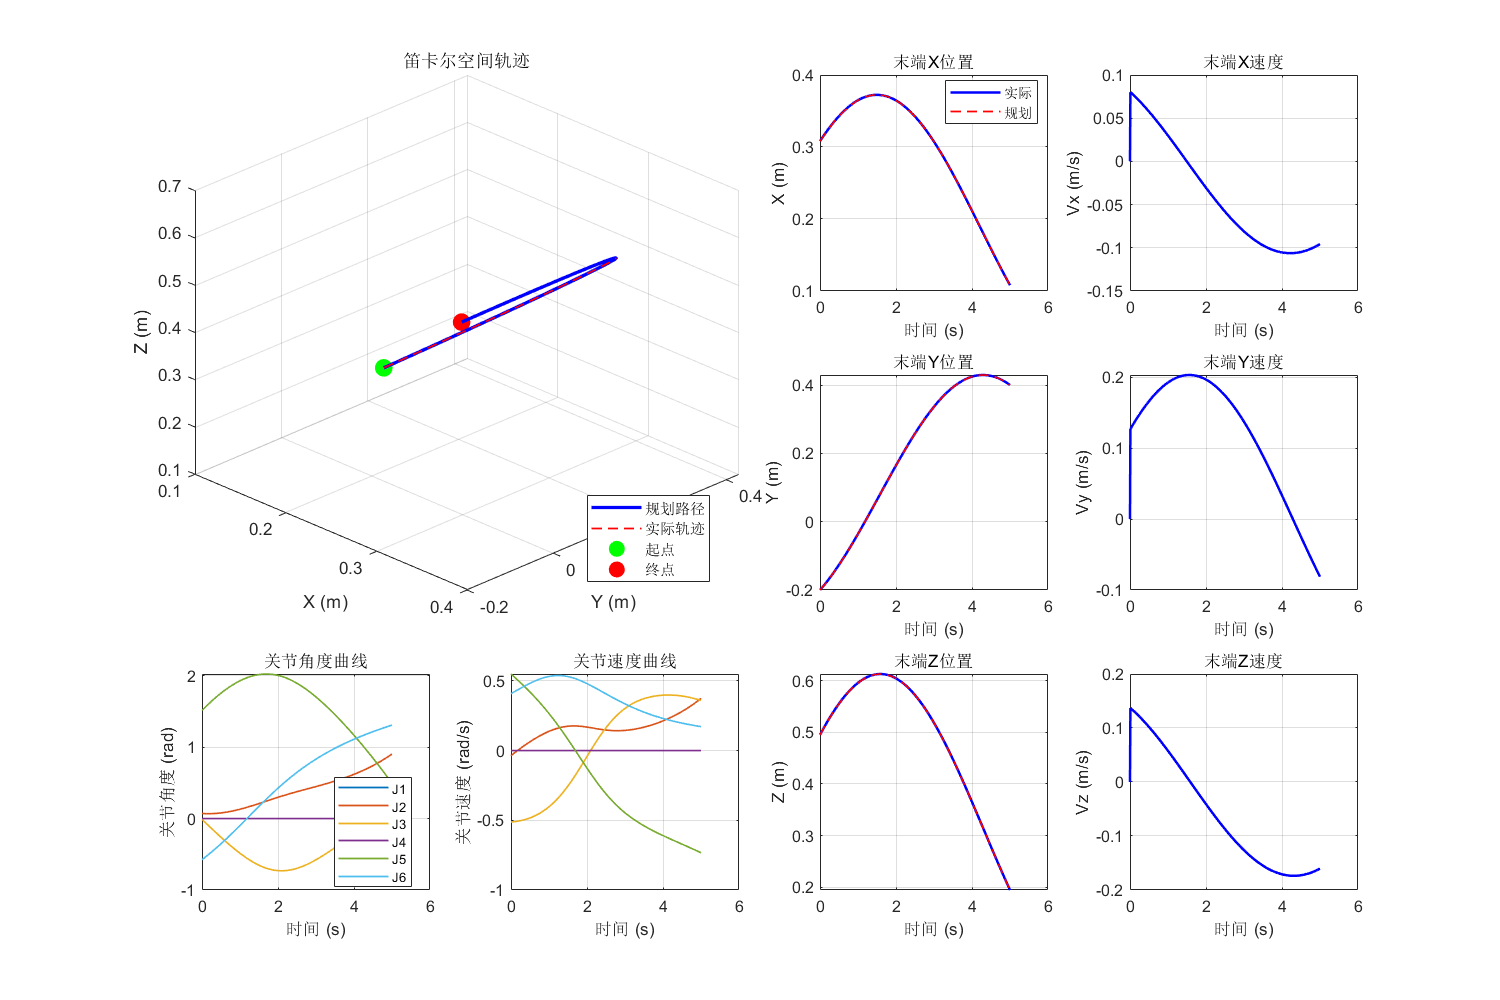

% 定义姿态（RPY角：roll, pitch, yaw）
orientation = [0, 0, 0];  % 假设末端执行器保持水平

% 定义时间参数
total_time = 5.0;  % 总时间5秒
time_points = linspace(0, total_time, num_points);

% 规划关节轨迹
q_traj = plan_joint_trajectory(EpsonC3_M, arc_points, qlim);

% 三次多项式插值（保证速度连续）
dt = 0.01;  % 采样时间0.01秒
[q_smooth, dq_smooth, ddq_smooth, time_vector] = ...
    cubic_polynomial_interpolation(q_traj, time_points, dt);

% 计算末端执行器轨迹
[ee_positions, ee_velocities] = calculate_ee_trajectory(EpsonC3_M, q_smooth, dq_smooth);

% 插值规划路径到相同时间点用于对比
if length(time_points) > 1
    arc_points_interp = interp1(time_points, arc_points, time_vector);
else
    arc_points_interp = repmat(arc_points, length(time_vector), 1);
end

% 可视化轨迹（不包括动画）
visualize_trajectory_without_animation(EpsonC3_M, q_traj, arc_points_interp, time_vector, ...
                                       q_smooth, dq_smooth, workspace, ee_positions, ee_velocities);

Animate: saving video --> .\videos\cartesion_CP_circle.mp4 with profile 'MPEG-4'
Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


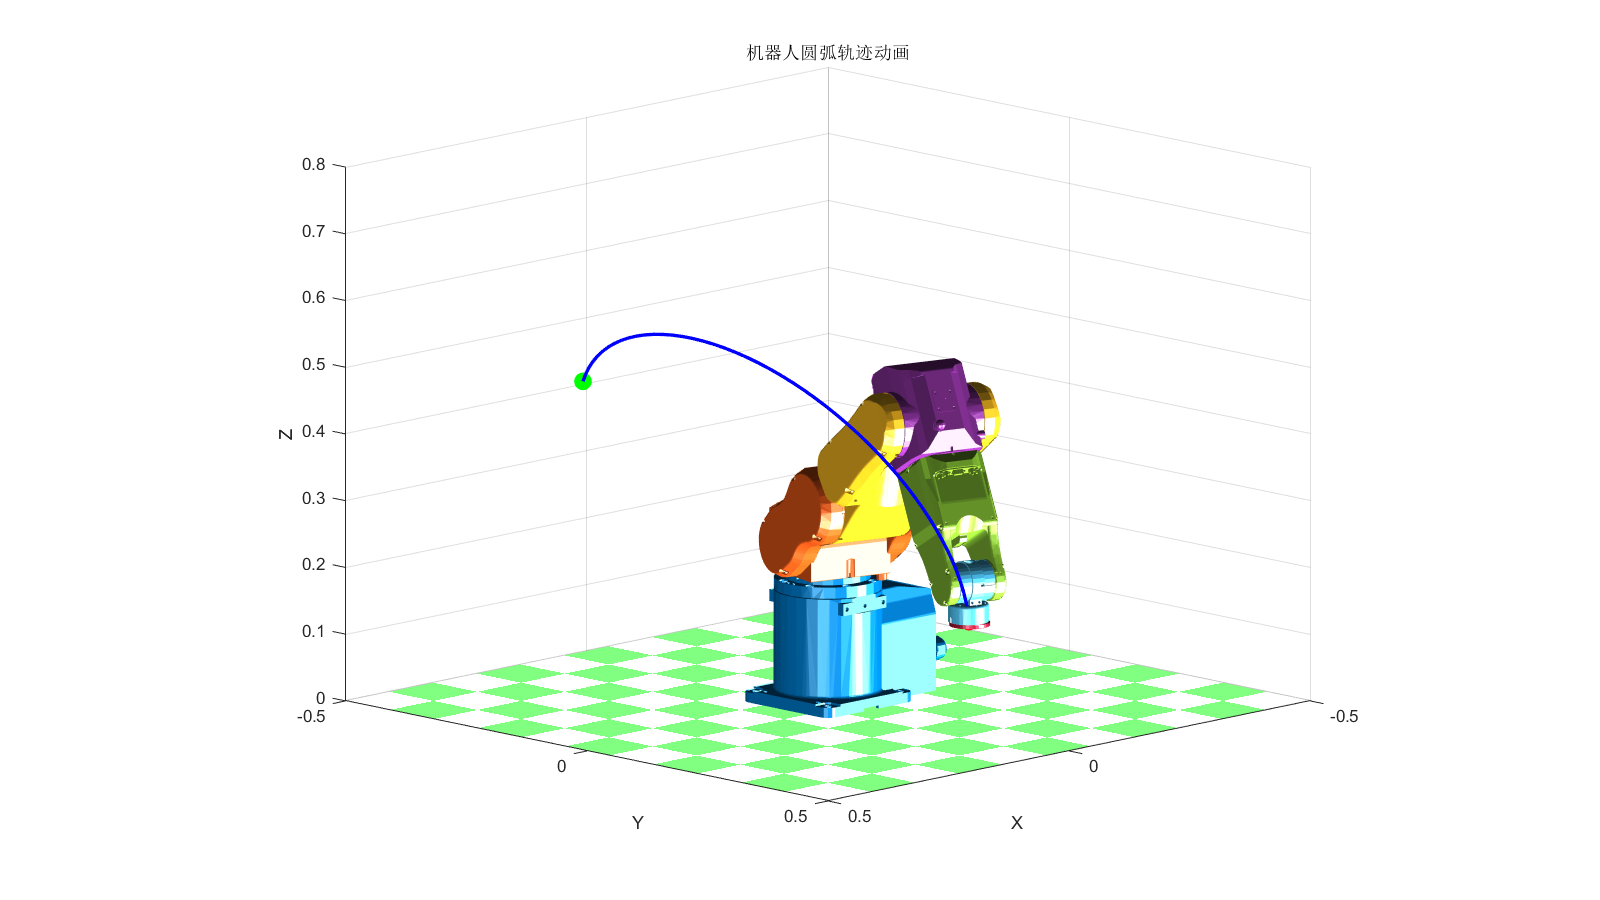

% 单独展示机器人动画
show_robot_animation(EpsonC3_M, q_smooth, arc_points, workspace, file_path);

% ============== 分析结果 ==============
fprintf('\n=== 轨迹分析结果 ===\n');


=== 轨迹分析结果 ===


fprintf('总时间: %.2f s\n', total_time);

总时间: 5.00 s


fprintf('平均速度: %.3f m/s\n', arc_length/total_time);

平均速度: 0.204 m/s


% 计算轨迹误差
if length(time_points) > 1
    position_error = zeros(length(time_vector), 1);
    for i = 1:length(time_vector)
        position_error(i) = norm(ee_positions(i,:) - arc_points_interp(i,:));
    end
    max_position_error = max(position_error);
    avg_position_error = mean(position_error);
    
    fprintf('最大位置误差: %.4f m\n', max_position_error);
    fprintf('平均位置误差: %.4f m\n', avg_position_error);
end

最大位置误差: 0.0002 m


平均位置误差: 0.0001 m


fprintf('\n最大关节速度:\n');


最大关节速度:


for i = 1:6
    fprintf('  关节%d: %.3f rad/s\n', i, max(abs(dq_smooth(:,i))));
end

  关节1: 0.538 rad/s
  关节2: 0.374 rad/s
  关节3: 0.512 rad/s
  关节4: 0.000 rad/s
  关节5: 0.733 rad/s
  关节6: 0.538 rad/s


fprintf('\n最大末端速度:\n');


最大末端速度:


fprintf('  Vx: %.3f m/s\n', max(abs(ee_velocities(:,1))));

  Vx: 0.106 m/s


fprintf('  Vy: %.3f m/s\n', max(abs(ee_velocities(:,2))));

  Vy: 0.203 m/s


fprintf('  Vz: %.3f m/s\n', max(abs(ee_velocities(:,3))));

  Vz: 0.174 m/s


fprintf('  总速度: %.3f m/s\n', max(sqrt(sum(ee_velocities.^2, 2))));

  总速度: 0.204 m/s


% 检查关节限制
fprintf('\n关节限制检查:\n');


关节限制检查:


for i = 1:6
    min_q = min(q_smooth(:,i));
    max_q = max(q_smooth(:,i));
    if min_q >= qlim(i,1) && max_q <= qlim(i,2)
        status = 'OK';
    else
        status = '超出限制';
    end
    fprintf('关节%d: [%.3f, %.3f] rad, 限制: [%.3f, %.3f] rad - %s\n', ...
            i, min_q, max_q, qlim(i,1), qlim(i,2), status);
end

关节1: [-0.575, 1.307] rad, 限制: [-2.967, 2.967] rad - OK
关节2: [0.068, 0.903] rad, 限制: [-2.793, 1.134] rad - OK
关节3: [-0.731, 0.174] rad, 限制: [-0.890, 3.927] rad - OK
关节4: [-0.000, 0.000] rad, 限制: [-3.491, 3.491] rad - OK
关节5: [0.493, 2.022] rad, 限制: [-2.356, 2.356] rad - OK
关节6: [-0.575, 1.307] rad, 限制: [-6.283, 6.283] rad - OK


function [center, radius, normal] = fit_circle_3d(p1, p2, p3) % 辅助函数：三点确定圆
    % center:圆心
    % radius:半径
    % normal:法向量

    % 三维空间中三点确定圆
    p1 = p1(:);
    p2 = p2(:);
    p3 = p3(:);

    % 计算三角形的边向量
    v1 = p2 - p1;
    v2 = p3 - p1;

    % 平面法向量
    normal = cross(v1, v2);
    if norm(normal) < eps
        error('三点共线，无法确定唯一的圆');
    end
    normal = normal / norm(normal);

    % 选择适当的局部坐标系
    if abs(normal(3)) > 0.9
        basis1 = [1;0;0];
    else
        basis1 = [0;0;1];
    end
    basis2 = cross(normal, basis1);
    basis2 = basis2 / norm(basis2);
    basis1 = cross(basis2, normal);

    % 投影到2D平面
    p1_2d = [dot(p1, basis1); dot(p1, basis2)];
    p2_2d = [dot(p2, basis1); dot(p2, basis2)];
    p3_2d = [dot(p3, basis1); dot(p3, basis2)];

    % 2D中计算圆心
    A = 2 * [p2_2d(1)-p1_2d(1), p2_2d(2)-p1_2d(2);
             p3_2d(1)-p1_2d(1), p3_2d(2)-p1_2d(2)];
    B = [p2_2d(1)^2-p1_2d(1)^2 + p2_2d(2)^2-p1_2d(2)^2;
         p3_2d(1)^2-p1_2d(1)^2 + p3_2d(2)^2-p1_2d(2)^2];

    center_2d = A \ B;

    % 转换回3D
    center = center_2d(1)*basis1 + center_2d(2)*basis2;
    radius = norm(p1 - center);
end


% 生成圆弧路径点
function [arc_points, arc_length, center, radius] = generate_arc(start_point, via_point, end_point, num_points)
    % 生成圆弧路径点
    % start_point: 起点 [x,y,z]
    % via_point: 中间点 [x,y,z]
    % end_point: 终点 [x,y,z]
    % num_points: 采样点数
    
    % 计算三点确定的圆
    [center, radius, normal_vec] = fit_circle_3d(start_point, via_point, end_point);
    
    % 创建局部坐标系
    if abs(normal_vec(3)) > 0.9
        x_axis = [1; 0; 0];
    else
        x_axis = cross([0;0;1], normal_vec);
        x_axis = x_axis / norm(x_axis);
    end
    y_axis = cross(normal_vec, x_axis);
    
    % 将点转换到局部坐标系
    R = [x_axis, y_axis, normal_vec];
    T = [R, center; 0, 0, 0, 1];
    
    local_start = (T \ [start_point, 1]')';
    local_via = (T \ [via_point, 1]')';
    local_end = (T \ [end_point, 1]')';
    
    % 计算起始角和终止角
    start_angle = atan2(local_start(2), local_start(1));
    via_angle = atan2(local_via(2), local_via(1));
    end_angle = atan2(local_end(2), local_end(1));
    
    % 调整角度连续性
    angles = [start_angle, via_angle, end_angle];
    for i = 2:3
        while angles(i) - angles(i-1) < -pi
            angles(i) = angles(i) + 2*pi;
        end
        while angles(i) - angles(i-1) > pi
            angles(i) = angles(i) - 2*pi;
        end
    end
    
    start_angle = angles(1);
    end_angle = angles(3);
    
    % 生成圆弧参数
    arc_angles = linspace(start_angle, end_angle, num_points);
    arc_points_local = [radius * cos(arc_angles); 
                        radius * sin(arc_angles); 
                        zeros(1, num_points); 
                        ones(1, num_points)];
    
    % 转换回全局坐标系
    arc_points = zeros(num_points, 3);
    for i = 1:num_points
        global_pt = T * arc_points_local(:, i);
        arc_points(i, :) = global_pt(1:3)';
    end
    
    % 计算弧长
    arc_length = radius * abs(end_angle - start_angle);
    
    fprintf('圆弧规划完成:\n');
    fprintf('  圆心: [%.3f, %.3f, %.3f]\n', center(1), center(2), center(3));
    fprintf('  半径: %.3f m\n', radius);
    fprintf('  弧长: %.3f m\n', arc_length);
    fprintf('  角度范围: %.1f° 到 %.1f°\n', rad2deg(start_angle), rad2deg(end_angle));
end

% 规划关节轨迹
function q_traj = plan_joint_trajectory(robot, cartesian_points, qlim)
    % 规划关节轨迹
    % robot: 机器人对象
    % cartesian_points: N×3的笛卡尔点
    % qlim: 关节限制
    
    hand_down = [0 pi 0]; % 机械臂的末端位姿永远为手部朝下
    N = size(cartesian_points, 1);
    
    % 计算每个点的逆运动学
    q_traj = zeros(N, robot.n);
    
    % 第一个点使用ikine
    % T_start = transl(cartesian_points(1,:)) * rpy2tr(orientation(1,:));
    T_start = transl(cartesian_points(1,:)) * rpy2tr(hand_down);
    q0 = zeros(1, robot.n);  % 初始猜测
    q_traj(1,:) = robot.ikine(T_start, 'q0', q0, 'mask', [1 1 1 1 1 1]);
    
    % 后续点使用上一个点作为初始猜测
    for i = 2:N
        T_i = transl(cartesian_points(i,:)) * rpy2tr(hand_down);
        q_traj(i,:) = robot.ikine(T_i, 'q0', q_traj(i-1,:), 'mask', [1 1 1 1 1 1]);
        
        % 检查关节限制
        for j = 1:robot.n
            if q_traj(i,j) < qlim(j,1) || q_traj(i,j) > qlim(j,2)
                fprintf('警告: 点%d关节%d超出限制: %.3f rad\n', i, j, q_traj(i,j));
            end
        end
    end
end

% 三次多项式插值
function [q_smooth, dq_smooth, ddq_smooth, time_vector] = cubic_polynomial_interpolation(q_points, time_points, dt)
    % 三次多项式插值
    % q_points: N×DOF的关节角度
    % time_points: 时间点
    % dt: 采样时间
    
    [N, dof] = size(q_points);
    time_vector = time_points(1):dt:time_points(end);
    M = length(time_vector);
    
    q_smooth = zeros(M, dof);
    dq_smooth = zeros(M, dof);
    ddq_smooth = zeros(M, dof);
    
    for i = 1:dof
        % 使用三次样条插值
        pp = spline(time_points, q_points(:,i)');
        
        % 计算插值
        q_smooth(:,i) = ppval(pp, time_vector)';
        
        % 计算一阶导数（速度）
        [breaks, coefs, l, k, d] = unmkpp(pp);
        dpp = mkpp(breaks, coefs(:,1:3).*repmat([3,2,1], l, 1), d);
        dq_smooth(:,i) = ppval(dpp, time_vector)';
        
        % 计算二阶导数（加速度）
        ddpp = mkpp(breaks, coefs(:,1:2).*repmat([6,2], l, 1), d);
        ddq_smooth(:,i) = ppval(ddpp, time_vector)';
    end
end

% 计算末端位置随时间的变化
function [ee_positions, ee_velocities] = calculate_ee_trajectory(robot, q_smooth, dq_smooth)
    % 计算末端执行器位置和速度
    % robot: 机器人对象
    % q_smooth: 平滑的关节轨迹
    
    M = size(q_smooth, 1);
    ee_positions = zeros(M, 3);  % x, y, z
    ee_velocities = zeros(M, 3); % vx, vy, vz
    
    for i = 1:M
        % 计算正向运动学
        T = robot.fkine(q_smooth(i,:));
        ee_positions(i,:) = T.t;
        
        % 计算雅可比矩阵和关节速度
        % if i > 1
        %     % 使用有限差分计算速度
        %     dt_sim = 0.01;  % 假设的时间间隔
        %     J = robot.jacob0(q_smooth(i,:));
        %     joint_vel = (q_smooth(i,:) - q_smooth(i-1,:))' / dt_sim;
        %     ee_velocities(i,:) = (J(1:3,:) * joint_vel)';
        % end
        if i <= M
            J = robot.jacob0(q_smooth(i,:));
            ee_velocities(i,:) = (J(1:3,:) * dq_smooth(i,:)')';
        end
    end
    
    % 第一点的速度设为0
    ee_velocities(1,:) = [0, 0, 0];
end

% 可视化轨迹（不包括动画）
function visualize_trajectory_without_animation(robot, q_traj, cartesian_points, time_vector, q_smooth, dq_smooth, workspace, ee_positions, ee_velocities)
    % 可视化轨迹（不包括动画）
    
    figure('Position', [100, 100, 1200, 800], 'Name', '轨迹分析');
    
    % 子图1: 笛卡尔空间轨迹
    subplot(3,4,[1,2,5,6]);
    plot3(cartesian_points(:,1), cartesian_points(:,2), cartesian_points(:,3), ...
          'b-', 'LineWidth', 2, 'DisplayName', '规划路径');
    hold on;
    plot3(ee_positions(:,1), ee_positions(:,2), ee_positions(:,3), ...
          'r--', 'LineWidth', 1, 'DisplayName', '实际轨迹');
    plot3(cartesian_points(1,1), cartesian_points(1,2), cartesian_points(1,3), ...
          'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', '起点');
    plot3(cartesian_points(end,1), cartesian_points(end,2), cartesian_points(end,3), ...
          'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', '终点');
    
    grid on; xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    title('笛卡尔空间轨迹');
    legend('Location', 'best');
    view(45, 30);
    
    % 子图2: 末端X分量
    subplot(3,4,3);
    plot(time_vector, ee_positions(:,1), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(time_vector, cartesian_points(:,1), 'r--', 'LineWidth', 1, 'DisplayName', '规划');
    grid on; xlabel('时间 (s)'); ylabel('X (m)');
    title('末端X位置');
    legend({'实际', '规划'}, 'Location', 'best');
    
    % 子图3: 末端Y分量
    subplot(3,4,7);
    plot(time_vector, ee_positions(:,2), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(time_vector, cartesian_points(:,2), 'r--', 'LineWidth', 1);
    grid on; xlabel('时间 (s)'); ylabel('Y (m)');
    title('末端Y位置');
    
    % 子图4: 末端Z分量
    subplot(3,4,11);
    plot(time_vector, ee_positions(:,3), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(time_vector, cartesian_points(:,3), 'r--', 'LineWidth', 1);
    grid on; xlabel('时间 (s)'); ylabel('Z (m)');
    title('末端Z位置');
    
    % 子图5: 末端速度X分量
    subplot(3,4,4);
    plot(time_vector, ee_velocities(:,1), 'b-', 'LineWidth', 1.5);
    grid on; xlabel('时间 (s)'); ylabel('Vx (m/s)');
    title('末端X速度');
    
    % 子图6: 末端速度Y分量
    subplot(3,4,8);
    plot(time_vector, ee_velocities(:,2), 'b-', 'LineWidth', 1.5);
    grid on; xlabel('时间 (s)'); ylabel('Vy (m/s)');
    title('末端Y速度');
    
    % 子图7: 末端速度Z分量
    subplot(3,4,12);
    plot(time_vector, ee_velocities(:,3), 'b-', 'LineWidth', 1.5);
    grid on; xlabel('时间 (s)'); ylabel('Vz (m/s)');
    title('末端Z速度');
    
    % 子图8: 关节角度
    subplot(3,4,9);
    colors = lines(6);
    for i = 1:6
        plot(time_vector, q_smooth(:,i), 'Color', colors(i,:), 'LineWidth', 1);
        hold on;
    end
    xlabel('时间 (s)'); ylabel('关节角度 (rad)');
    title('关节角度曲线');
    legend({'J1','J2','J3','J4','J5','J6'}, 'Location', 'best', 'FontSize', 8);
    grid on;
    
    % 子图9: 关节速度
    subplot(3,4,10);
    for i = 1:6
        plot(time_vector, dq_smooth(:,i), 'Color', colors(i,:), 'LineWidth', 1);
        hold on;
    end
    xlabel('时间 (s)'); ylabel('关节速度 (rad/s)');
    title('关节速度曲线');
    grid on;
end

% 单独展示机器人动画
function show_robot_animation(robot, q_smooth, cartesian_points, workspace, file_path)
    % 单独展示机器人动画
    figure('Position', [100, 100, 1280, 720], 'Name', 'CP曲线路径', 'Renderer','opengl');
    % figure('Position', [100, 100, 1280, 720], 'Name', 'CP曲线轨迹规划');
    
    grid on; xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    title('机器人圆弧轨迹动画');
    axis(workspace);
    view(45, 30);
    hold on;
    
    % 绘制圆弧路径
    plot3(cartesian_points(:,1), cartesian_points(:,2), cartesian_points(:,3), ...
          'b-', 'LineWidth', 2, 'DisplayName', '规划路径');
    plot3(cartesian_points(1,1), cartesian_points(1,2), cartesian_points(1,3), ...
          'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', '起点');
    plot3(cartesian_points(end,1), cartesian_points(end,2), cartesian_points(end,3), ...
          'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', '终点');
    hold on;
    
    % 绘制机械臂动画
    light('Position', [1, 1, -1], 'color', 'w'); % 打光，不然机械臂有点暗
    light('Position', [1, 1, 1], 'color', 'w'); % 打光，不然机械臂有点暗
    robot.plot3d(q_smooth(:,:), 'tilesize', 0.1, 'path', file_path, 'nowrist', 'trail', {'b', 'linewidth', 1}, 'workspace', workspace, 'scale', 0.5, 'fps', 20, ...
    'movie', '.\videos\cartesion_CP_circle.mp4');    
end